clc; clear; close all;

% Load CSV
data = readmatrix('project_1');

mic1 = data(:,1);
mic2 = data(:,2);
mic3 = data(:,3);
% mic4 = data(:,4);

mic1 = mic1(1:4000)

mic1 =          935
         950
         964
         977
         983
         989
         997
        1001
        1006
        1008


mic2 = mic1(1:4000)

mic2 =          935
         950
         964
         977
         983
         989
         997
        1001
        1006
        1008


mic3 = mic1(1:4000)

mic3 =          935
         950
         964
         977
         983
         989
         997
        1001
        1006
        1008


mic4 = mic1(1:4000)

mic4 =          935
         950
         964
         977
         983
         989
         997
        1001
        1006
        1008



Fs = 16000;              % Sampling frequency (Hz)
Ts = 1/Fs;               % Sampling period
%N = length(mic1);        % Number of samples
N = 4000

N = 4000

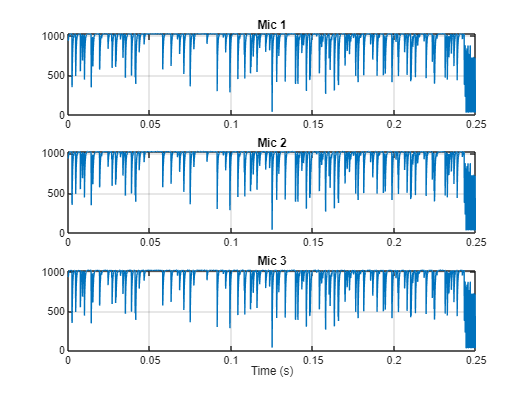

t = (0:N-1)*Ts;          % Time vector


figure;

subplot(3,1,1);
plot(t, mic1);
title('Mic 1'); grid on;

subplot(3,1,2);
plot(t, mic2);
title('Mic 2'); grid on;

subplot(3,1,3);
plot(t, mic3);
title('Mic 3'); grid on;

% subplot(4,1,4);
% plot(t, mic4);
% title('Mic 4'); grid on;

xlabel('Time (s)');

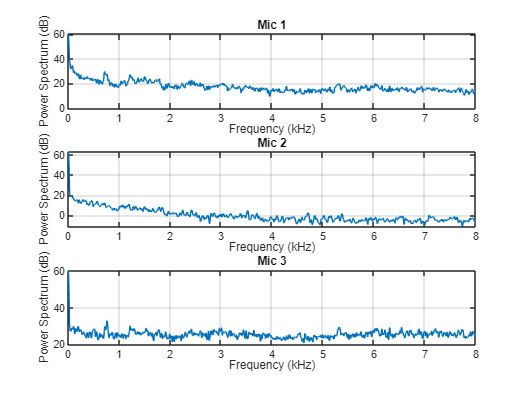

% Plot Freq
figure;

for i = 1:3
    subplot(3,1,i);
    pspectrum(data(:,i), Fs);
    title(['Mic ', num2str(i)]);
end

mic =          935
         950
         964
         977
         983
         989
         997
        1001
        1006
        1008


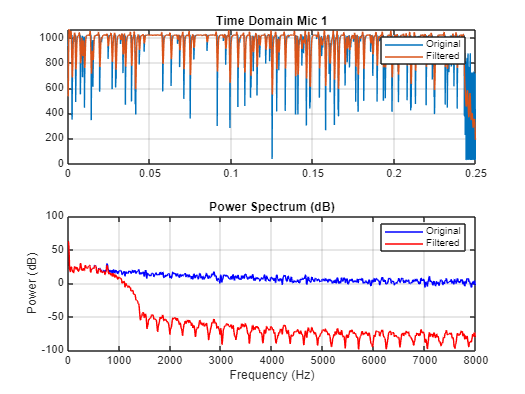

mic =         1021
        1022
        1022
        1023
        1022
        1023
        1021
        1021
        1023
        1023


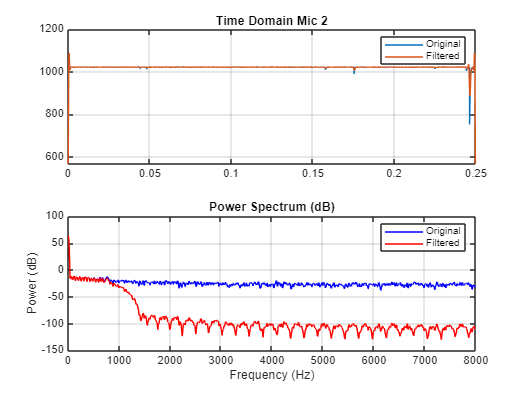

mic =         1023
        1022
        1019
         864
          29
        1023
        1023
        1022
        1022
        1022


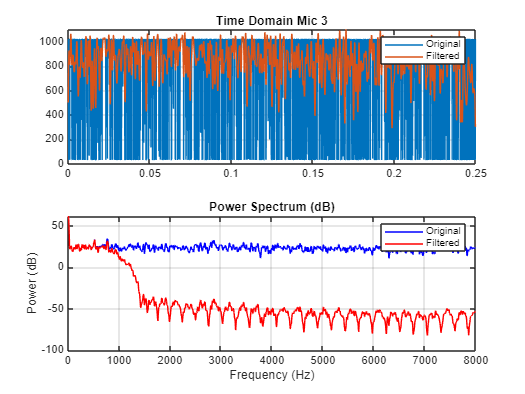

% Lowpass 
% Lowpass 
for i = 1:3
    mic = data(:,i);
    mic = mic(1:4000)
    mic_f = lowpass(mic, 300, Fs);

    figure;

    % Time domain
    subplot(2,1,1);
    plot(t, mic); hold on;
    plot(t, mic_f);
    title(['Time Domain Mic ', num2str(i)]);
    legend('Original','Filtered');
    grid on;

    % Frequency domain (pspectrum in dB)
    subplot(2,1,2);

    [p1,f1] = pspectrum(mic, Fs);
    [p2,f2] = pspectrum(mic_f, Fs);

    plot(f1, 10*log10(p1), 'b'); hold on;
    plot(f2, 10*log10(p2), 'r');

    title('Power Spectrum (dB)');
    xlabel('Frequency (Hz)');
    ylabel('Power (dB)');
    legend('Original','Filtered');
    grid on;
end